## Программа для восстановления состояния, заданого матрицей плотности

Возможно восстановление как чистого, так и смешанного состояния

clc
clear
close all
addpath('C:\Users\Alexey\OneDrive\QI\Qubits\Protocols');
addpath('C:\Users\Alexey\OneDrive\QI\Qubits\Tomography');
rng(1,'twister');

%% Начальные условия
S = 1;             % Число кубитов S = 1 - один кубит
n_exp = 1000;      % Число экспериментов
n = 1000;          % Выборка в каждом эксперименте
a = 0.5;           % Параметр сходимости
x = X_Octahedron; % Выбранный протокол

%% Ортогональные состояния, на основе которых строится матрица плотности
psi0 = [1; 0];
psi1 = [0; 1];

phi0 = 1 / sqrt(2) * [1; 1];
phi1 = 1 / sqrt(2) * [1; -1];

chi0 = 1 / sqrt(2) * [1; 1i];
chi1 = 1 / sqrt(2) * [1; -1i];

%% Выбранное состояние
p = 0.5;
po = create_po_matrix(psi0,chi0,p,1); % Матрица плотности
po = kron_S(po,S);

x = kron_S(x, S);

**m** - число строк в аппаратной матрице

**s** - размерность системы

[m, s] = size(x) 

m = 8

s = 2

                 
%% Задание времени экспозиции для измерения в каждом базисе
t = time_for_protocol(n, s, m, 'uniform');
                 
%% Восстановление с рангом r = 1
% Если присутсвует смесь с маленьким весом,
% то ранг нужно переопределить
r = rank(po)

r = 2


%% Расчет вероятности регистрации событий {r = 1}
lambda = lambda_for_protocol(x, m, po);

%% Новая аппаратная матрица {r = 1}
X = X_for_mixed(r, x);

%% Новые проекторы {r = 1}
Lambda = Lambda_for_mixed(X);

%% Матрица I {r = 1}
I = I_for_protocol(Lambda, r, s, t, m);

% Набор результатов потерь точности
dF_set = zeros(n_exp,1); 
 
for n_e=1:n_exp
    
if(mod(n_e,100) == 0)
    fprintf('Проведено %d экспериментов\n', n_e);
end
%% Генерация числа фотонов, подчиняющихся распределению Пуассона
K = generate_K(lambda, t);

%% Итерационная процедура 
% C1 - Первое приближение
C1 = first_approximation(x, t, K, r);
% C_tmp - Временная переменная
C_tmp = C_temporary(r, s);
%Число шагов
counter = 3;
C1 = iteraction_procedure(I, C1, C_tmp, Lambda, K, r, s, m, a, counter);

%% Процедура, обратная процедуре очищения
po1 = reverse_purification(C1, r, s);

%% Результат
dF_set(n_e) = 1 - fidelity(po, po1);

end

Проведено 100 экспериментов
Проведено 200 экспериментов
Проведено 300 экспериментов
Проведено 400 экспериментов
Проведено 500 экспериментов
Проведено 600 экспериментов
Проведено 700 экспериментов
Проведено 800 экспериментов
Проведено 900 экспериментов
Проведено 1000 экспериментов



[dF_average_teor, d] = dF_mixed_no_noise_new(x, po, t, n, r);
dF_average_exp = mean(dF_set)

dF_average_exp = 0.0024

dF_average_teor

dF_average_teor = 0.0023

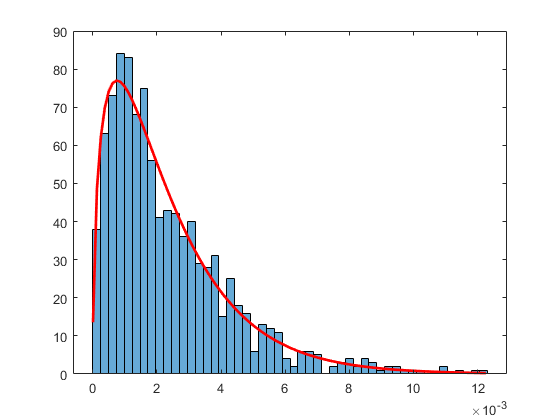

%% Построение графиков
plot_hist_and_generalchi2pdf(dF_set, d, n_exp)